# **STEP_02:  **Explore a simple cantilever - **IMPACT excitation test (simulate)**

Let's get familiar with the Flexible Beam block in Simscape Multibody

- [https://www.mathworks.com/help/releases/R2026a/sm/ref/flexiblerectangularbeam.html](https://www.mathworks.com/help/releases/R2026a/sm/ref/flexiblerectangularbeam.html)

And what better way, than to model and VERIFY the behavior of a simple cantilever beam 

**Objective:**

- Perform an IMPACT load test on the cantilever model (Simscape Multibody) and measure the applied FORCE and RESPONSE.

- ***NOTE:***  In part 2 we'll extract the Modal properties from this measured timeseries data.

- [`bh_cant_STEP_03_IMPACT_part_2.mlx`](matlab:  open  bh_cant_step_03_impact_part_2.mlx)

So here is the Cantilever system that we're going to focus on - and note the orientation of the **Inertial reference frame**.

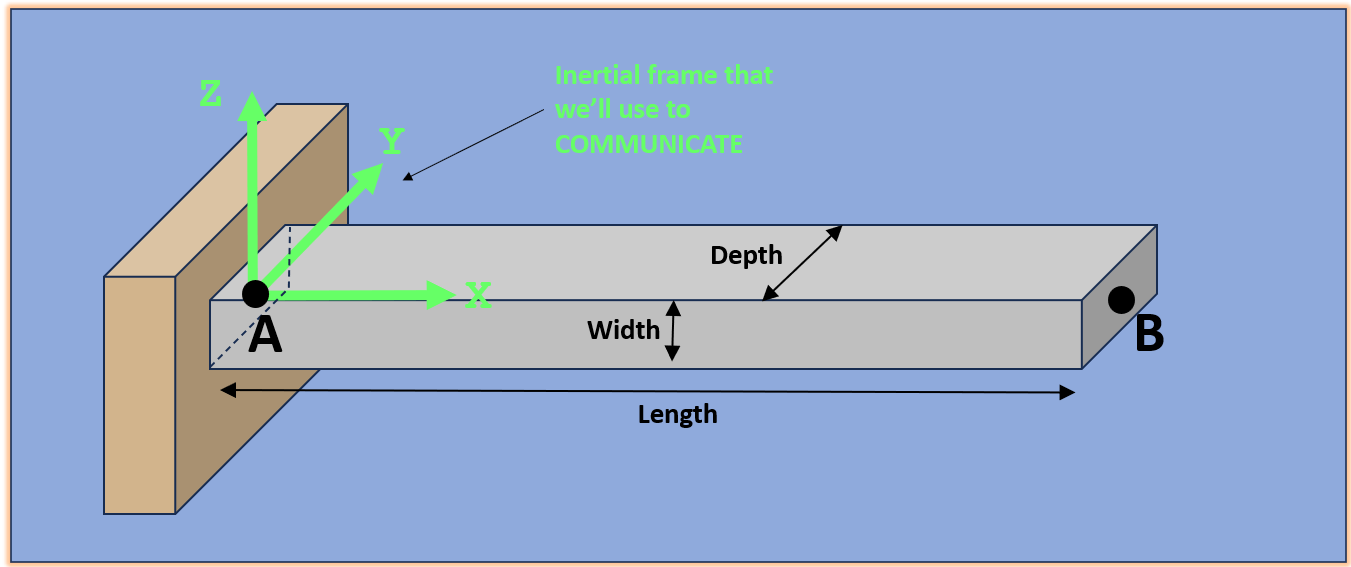

**Some comments about the Simulation**:

- We have disabled GRAVITY so that the self weight load is ZERO

- EXCITATION:

- We apply a vertical **impact load to the TIP** of the cantilever

- RESPONSE:

- We measure the vertical **displacement** response at the TIP

- The timeseries data (Applied FORCE and displacement RESPONSE) are logged to an **EXCEL file**

- `bh_RAW_IMPACT_MEAS.xlsx`

## Clear the workspace

clear

## Define the BEAM (we'll eventually call it a COLUMN)

Define the beam's cross section.  See:

- [`bh_create_column_OBJ`](matlab:  edit  bh_create_column_OBJ)

- [`bh_flex_column_CLS`](matlab: edit bh_flex_column_CLS)

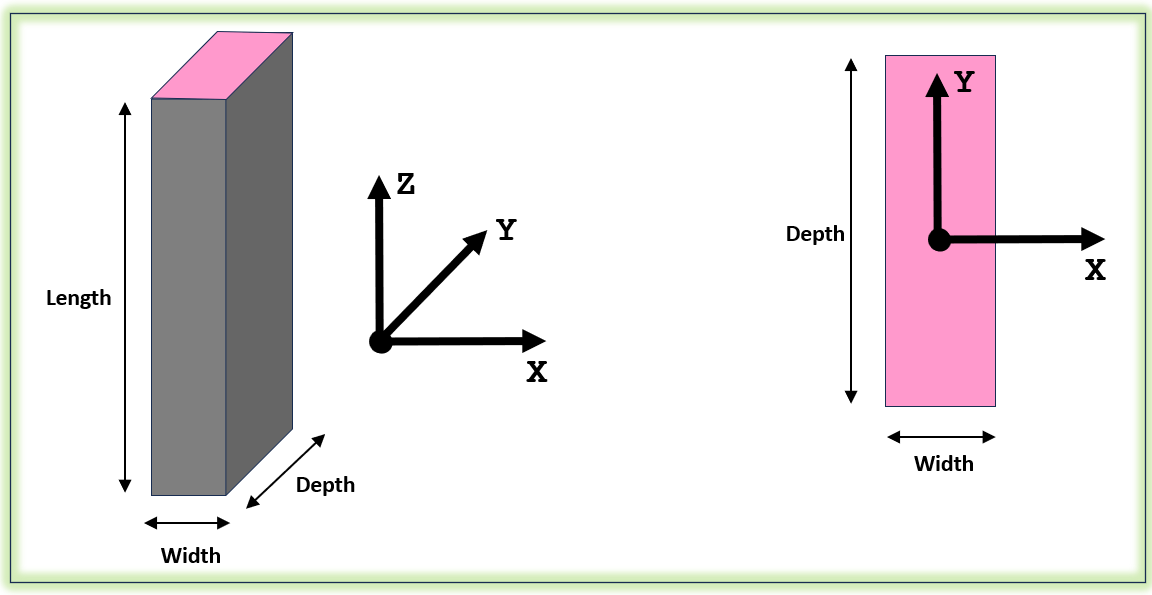

col_OBJ              = bh_create_column_OBJ(Width=1/1000, Depth=25.4/1000, Length=300/1000, density=7800);

 **NOTE:**  choosing a damping ratio less than say 5e-3 ... really slows down the Simulink solver and makes the simulation run too slow (even for the specialist STIFF solvers like `ode23t`)

col_OBJ.damp_ratio =  5e-3; 
col_OBJ.num_eles     = 5;

So what attributes do we have

col_OBJ

col_OBJ =   bh_flex_column_CLS with properties:

          WIDTH_x: 1.0000e-03
          DEPTH_y: 0.0254
         LENGTH_z: 0.3000
          density: 7800
      E_GPa_Young: 200
        v_Poisson: 0.3000
     damp_M_coeff: 0
     damp_K_coeff: 1.0000e-03
       damp_ratio: 0.0050
         num_eles: 5
    num_ret_modes: 5
          BC_case: "FIXED_FIXED_WITH_SWAY"
             mass: 0.0594
              vol: 7.6200e-06
               Ix: 1.3656e-09
               Iy: 2.1167e-12
               Kx: 188.1481
             area: 2.5400e-05


## Define the Environment

g_vector = [0, 0, -9.80665];

## Open and run a Simulink model

When the Simulink model opens:

- Click the RUN icon to run the simulation

- Observe the animation of the cantilever's response

- Confirm that an EXCEL file named `bh_RAW_IMPACT_MEAS.xlsx` was created

open_system("bh_cantilever_IMPACT_test.slx")